close all;
clear all;
clc;


% Pior caso do sistema e com a carga nominal reduzida, entao projeto o
% controlador para carga de 10% para garantir o funcionamento do sistema 

F = 5000

F = 5000



% Reprojeto do controlador
s = tf('s');

% planta
potencia = 100 % 100%

potencia = 100

Vs = 50 % 50 V

Vs = 50

L = 0.008333333333333333

L = 0.0083

C = 5e-05 % 0.18uF

C = 5.0000e-05

R = 41.666666666666664 / (potencia/100) % 41.7 ohms -> (100% da potencia nominal)

R = 41.6667

Gvd = (Vs/(L*C)) / (s^2 + (1/(R*C))*s + (1/(L*C)))


Gvd =
 
         1.2e08
  --------------------
  s^2 + 480 s + 2.4e06
 
Continuous-time transfer function.



% filtro
Hvd = (9869604.40108936) / (1.0*s^2 + 5441.39809270*s + 9869604.40108936)


Hvd =
 
         9.87e06
  ----------------------
  s^2 + 5441 s + 9.87e06
 
Continuous-time transfer function.


Cp = (7.0925e-06 * (s+5.789e04)) / s


Cp =
 
  7.093e-06 s + 0.4106
  --------------------
           s
 
Continuous-time transfer function.


T = feedback(Gvd * Cp, Hvd)


T =
 
           851.1 s^3 + 5.39e07 s^2 + 2.765e11 s + 4.863e14
  ------------------------------------------------------------------
  s^5 + 5921 s^4 + 1.488e07 s^3 + 1.78e10 s^2 + 2.37e13 s + 4.863e14
 
Continuous-time transfer function.


step(T);

% planta
potencia = 10 % 10%

potencia = 10

Vs = 50 % 50 V

Vs = 50

L = 0.008333333333333333

L = 0.0083

C = 5e-05 % 0.18uF

C = 5.0000e-05

R = 41.666666666666664 / (potencia/100) % 41.7 ohms -> (100% da potencia nominal)

R = 416.6667

Gvd = (Vs/(L*C)) / (s^2 + (1/(R*C))*s + (1/(L*C)))


Gvd =
 
        1.2e08
  -------------------
  s^2 + 48 s + 2.4e06
 
Continuous-time transfer function.



% filtro
Hvd = (9869604.40108936) / (1.0*s^2 + 5441.39809270*s + 9869604.40108936)


Hvd =
 
         9.87e06
  ----------------------
  s^2 + 5441 s + 9.87e06
 
Continuous-time transfer function.


Cp = (7.0925e-06 * (s+5.789e04)) / s


Cp =
 
  7.093e-06 s + 0.4106
  --------------------
           s
 
Continuous-time transfer function.


T = feedback(Gvd * Cp, Hvd)


T =
 
            851.1 s^3 + 5.39e07 s^2 + 2.765e11 s + 4.863e14
  -------------------------------------------------------------------
  s^5 + 5489 s^4 + 1.253e07 s^3 + 1.353e10 s^2 + 2.37e13 s + 4.863e14
 
Continuous-time transfer function.


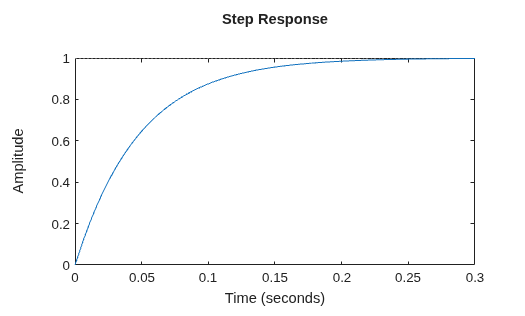

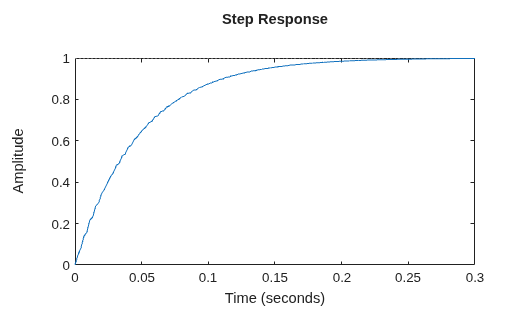

step(T);


% ==========================================================
% DISCRETIZAÇÃO, FUNÇÃO DE TRANSFERÊNCIA E EQUAÇÃO DE DIFERENÇAS
% ==========================================================
Ts = 1 / F; % Período de amostragem (ajuste conforme sua frequência de chaveamento)
Cp_z = c2d(Cp, Ts, 'tustin');

disp('--- FUNÇÃO DE TRANSFERÊNCIA DISCRETA DO CONTROLADOR Cp(z) ---');

--- FUNÇÃO DE TRANSFERÊNCIA DISCRETA DO CONTROLADOR Cp(z) ---


disp(Cp_z);

  tf with properties:

       Numerator: {[4.8151e-05 3.3966e-05]}
     Denominator: {[1 -1]}
        Variable: 'z'
         IODelay: 0
      InputDelay: 0
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 2.0000e-04
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]




% Extração dos coeficientes para a equação de diferenças
[num, den] = tfdata(Cp_z, 'v');
b0 = num(1) / den(1);
b1 = num(2) / den(1);
a1 = den(2) / den(1);

disp('--- EQUAÇÃO DE DIFERENÇAS DO CONTROLADOR ---');

--- EQUAÇÃO DE DIFERENÇAS DO CONTROLADOR ---


fprintf('u[k] = %.6f * e[k] + %.6f * e[k-1] - (%.6f) * u[k-1]\n\n', b0, b1, a1);

u[k] = 0.000048 * e[k] + 0.000034 * e[k-1] - (-1.000000) * u[k-1]

